# **Implementation of a Quantum Luenberg observer for System cavity : **

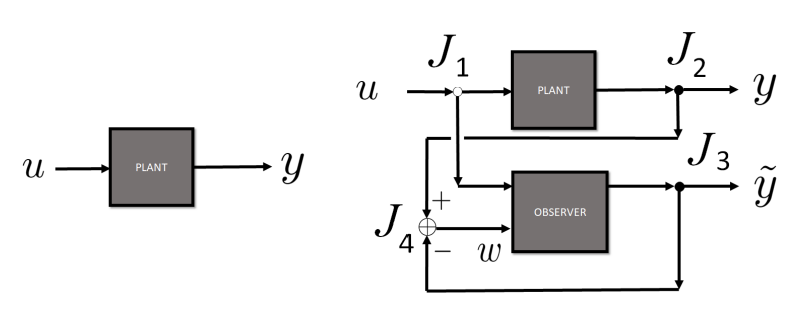

This is the classical the Luenberg Observer. 

# **The plant : System Cavity**

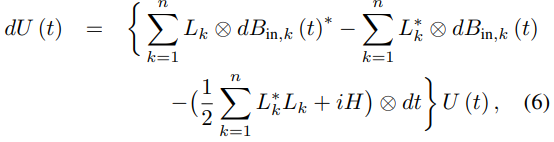

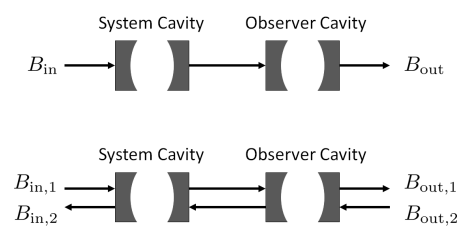

# **Quantum Luenberg observer (Non verifiable)**

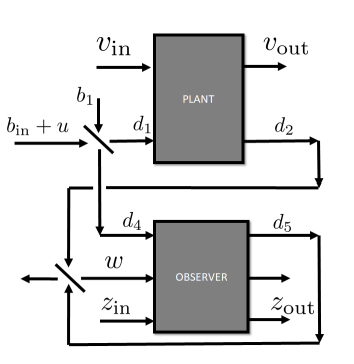

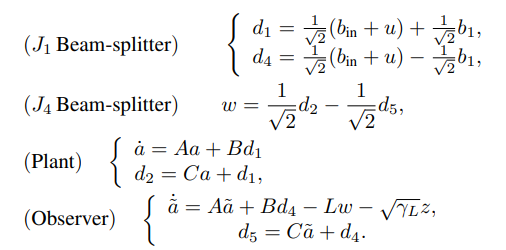

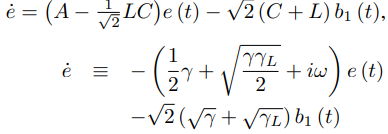

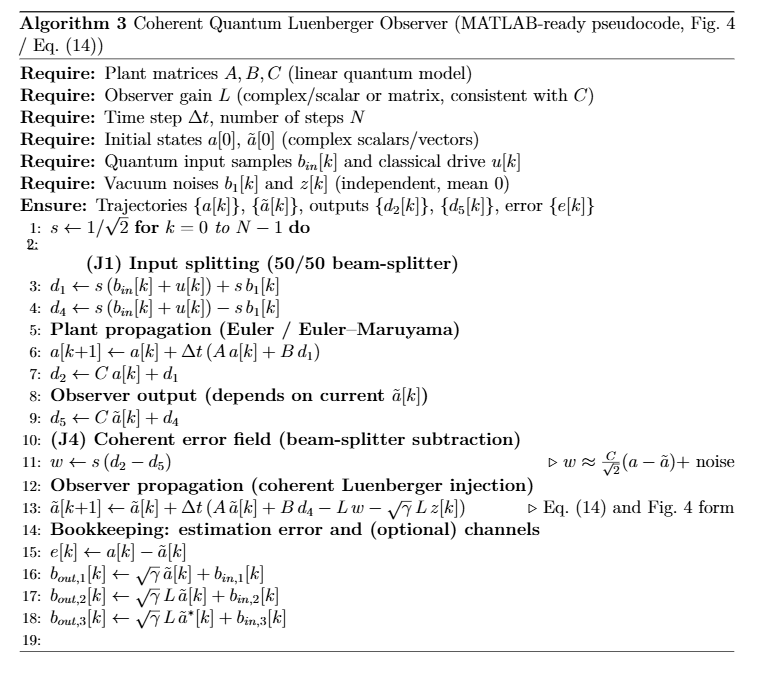

function sim = cq_luenberger_sim(varargin)
% Coherent Quantum Luenberger Observer (Fig.4 / Eq.(14)) - MATLAB simulation
%
% This is a *numerical* simulation of the QSDE-based model using
% an Euler / Euler-Maruyama discretization on complex amplitudes.
% Vacuum fields are modeled as i.i.d. complex Gaussian samples.
%
% Outputs:
%   sim.a, sim.atil, sim.e    : state trajectories (plant, observer, error)
%   sim.d1, sim.d4            : J1 beam-splitter outputs (inputs to plant/obs)
%   sim.d2, sim.d5            : output fields of plant/obs
%   sim.w                     : coherent error field (J4 beam-splitter)
%   sim.params                : parameters used
%
% Example:
%   sim = cq_luenberger_sim('N',2e4,'dt',1e-4,'gamma',2,'omega',20,'L',1.2);
%   figure; plot(real(sim.e)); title('Re(e[k])');

% -------------------- Defaults --------------------
p = inputParser;
p.addParameter('N',          20000);
p.addParameter('dt',         1e-4);
p.addParameter('gamma',      1.0);
p.addParameter('omega',      10.0);
p.addParameter('L',          1.0);   % coherent observer gain (scalar here)
p.addParameter('a0',         1+0i);
p.addParameter('atil0',      0+0i);
p.addParameter('u',          []);    % length N vector, default zeros
p.addParameter('bin',        []);    % length N complex vector, default vacuum
p.addParameter('b1',         []);    % length N complex vector, default vacuum
p.addParameter('z',          []);    % length N complex vector, default vacuum
p.addParameter('seed',       1);     % RNG seed for reproducibility
p.parse(varargin{:});
prm = p.Results;

N     = prm.N;
dt    = prm.dt;
gamma = prm.gamma;
omega = prm.omega;
L     = prm.L;

% -------------------- Matrices (single mode) --------------------
% Plant:  a_dot = A a + B d1,  d2 = C a + d1
% with A = -(gamma/2 + i omega), B = -sqrt(gamma), C = sqrt(gamma)
A = -(gamma/2 + 1i*omega);
B = -sqrt(gamma);
C =  sqrt(gamma);

% -------------------- Inputs --------------------
rng(prm.seed);

if isempty(prm.u),   u   = zeros(N,1); else, u = prm.u(:); end
if numel(u) ~= N, error('u must have length N'); end

% Vacuum fields (simple model): i.i.d CN(0,1) samples
vac = @(n) (randn(n,1) + 1i*randn(n,1))/sqrt(2);

if isempty(prm.bin), bin = vac(N); else, bin = prm.bin(:); end
if isempty(prm.b1),  b1  = vac(N); else, b1  = prm.b1(:); end
if isempty(prm.z),   z   = vac(N); else, z   = prm.z(:); end

if any([numel(bin),numel(b1),numel(z)] ~= N)
    error('bin, b1, z must have length N');
end

% -------------------- Preallocate --------------------
a    = zeros(N+1,1);  a(1)    = prm.a0;
atil = zeros(N+1,1);  atil(1) = prm.atil0;

d1 = zeros(N,1); d4 = zeros(N,1);
d2 = zeros(N,1); d5 = zeros(N,1);
w  = zeros(N,1);
e  = zeros(N,1);

s = 1/sqrt(2);

% -------------------- Time stepping --------------------
for k = 1:N
    % (J1) input splitting (beam-splitter)
    d1(k) = s*(bin(k) + u(k)) + s*b1(k);
    d4(k) = s*(bin(k) + u(k)) - s*b1(k);

    % Plant output (use current state a(k))
    d2(k) = C*a(k) + d1(k);

    % Observer output (use current state atil(k))
    d5(k) = C*atil(k) + d4(k);

    % (J4) coherent error field
    w(k)  = s*(d2(k) - d5(k));

    % Plant propagation (Euler)
    a(k+1) = a(k) + dt*(A*a(k) + B*d1(k));

    % Observer propagation (Euler) :  atil_dot = A atil + B d4 - L w - sqrt(gamma) L z
    atil(k+1) = atil(k) + dt*(A*atil(k) + B*d4(k) - L*w(k) - sqrt(gamma)*L*z(k));

    % Error (state error)
    e(k) = a(k) - atil(k);
end

% -------------------- Pack outputs --------------------
sim.a     = a;
sim.atil  = atil;
sim.e     = e;
sim.d1    = d1;  sim.d4 = d4;
sim.d2    = d2;  sim.d5 = d5;
sim.w     = w;

sim.params = struct('N',N,'dt',dt,'gamma',gamma,'omega',omega,'L',L, ...
                    'A',A,'B',B,'C',C,'seed',prm.seed);

end

%% Demo + plots for Fig.4 Coherent Quantum Luenberger Observer
% (uses cq_luenberger_sim.m from previous message)

clear; close all; clc;

% --- Parameters (tune these) ---
N     = 40000;      % steps
dt    = 2e-4;       % time step
gamma = 2.0;        % damping
omega = 20.0;       % frequency
L     = 1.5;        % observer gain

% initial conditions (plant nonzero, observer zero)
a0    = 1.0 + 0.3i;
atil0 = 0.0 + 0.0i;

% optional classical drive u(t)
u = zeros(N,1);     % set e.g. u = 0.2*sin(2*pi*1*(0:N-1)'*dt);

% --- Run simulation ---
sim = cq_luenberger_sim('N',N,'dt',dt,'gamma',gamma,'omega',omega,'L',L, ...
                        'a0',a0,'atil0',atil0,'u',u,'seed',1);

t = (0:N)'*dt;          % time for states (N+1)
tk = (0:N-1)'*dt;       % time for fields (N)

% ---------- Plot 1: Plant vs Observer estimate ----------
% In this paper/config, the convergence is typically  -ã(t) -> a(t)
figure;
plot(t, real(sim.a), 'LineWidth', 1.2); hold on;
plot(t, real(-sim.atil), 'LineWidth', 1.2);
grid on; xlabel('t'); ylabel('Real part');
legend('Re(a(t)) (plant)','Re(-\tilde{a}(t)) (observer)');
title('Fig.4: Tracking (typically -\tilde{a}(t) \rightarrow a(t))');

% ---------- Plot 2: Estimation error e(t) = a(t) - ã(t) ----------
figure;
plot(tk, abs(sim.e), 'LineWidth', 1.2);
grid on; xlabel('t'); ylabel('|e(t)|');
title('Estimation error magnitude |e(t)|');

% ---------- Plot 3: Coherent error field w(t) = (d2-d5)/sqrt(2) ----------
figure;
plot(tk, real(sim.w), 'LineWidth', 1.2);
grid on; xlabel('t'); ylabel('Re(w(t))');
title('Coherent error field w(t) from the J4 beam-splitter');

% ---------- Plot 4: Plant and observer outputs d2 and d5 ----------
figure;
plot(tk, real(sim.d2), 'LineWidth', 1.0); hold on;
plot(tk, real(sim.d5), 'LineWidth', 1.0);
grid on; xlabel('t'); ylabel('Real part');
legend('Re(d_2(t)) plant output','Re(d_5(t)) observer output');
title('Outputs d_2 and d_5 (Fig.4)');

% ---------- Quick steady-state error variance estimate ----------
% <e* e> ~ mean(|e|^2) over the last 20% of samples (crude Monte Carlo)
idx = round(0.8*N):N-1;
e_var_est = mean(abs(sim.e(idx)).^2);
fprintf('Estimated steady-state <e*e> ~ %.4g (Monte Carlo)\n', e_var_est);

Estimated steady-state <e*e> ~ 2562 (Monte Carlo)


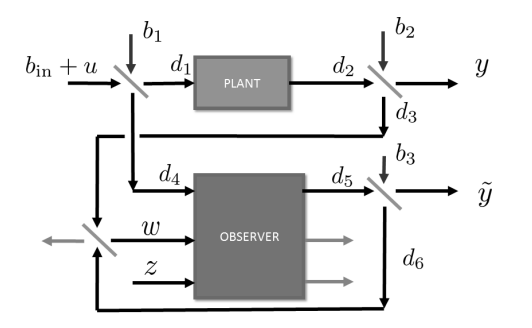

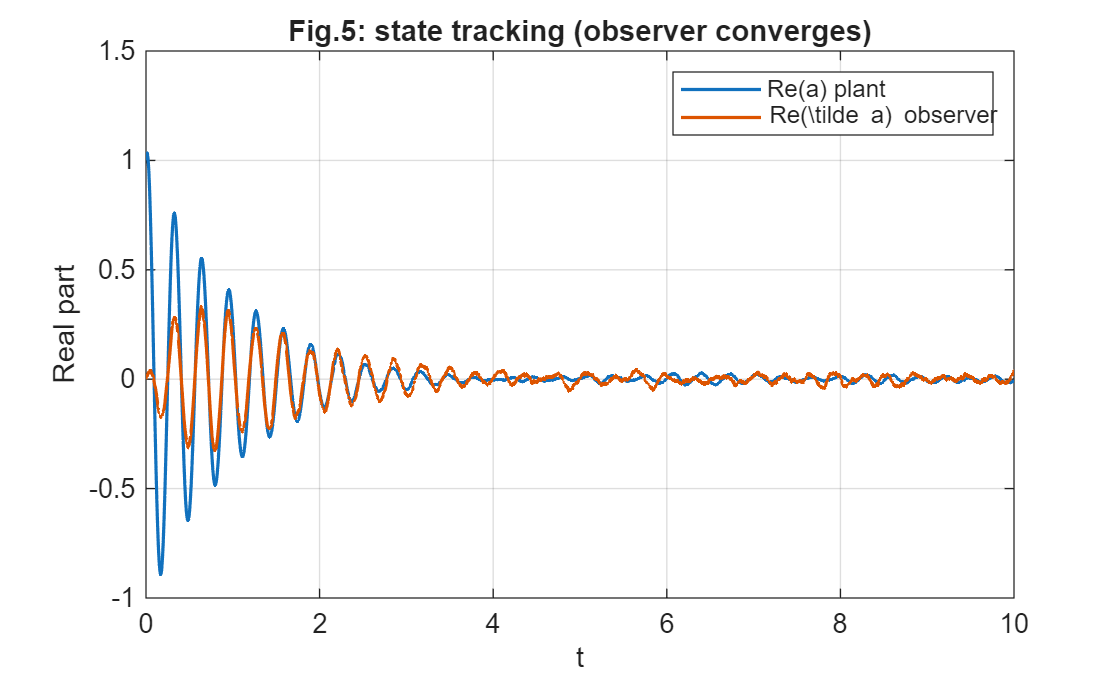

function sim = cq_luenberger_fig5_sim(varargin)
% Coherent Quantum Luenberger Observer - Figure 5 style interconnection
% (with additional beam splitters producing y and ytil, and error from d3,d6)
%
% Plant (single mode):
%   a_dot = A a + B d1
%   d2    = C a + d1
%
% Observer:
%   atil_dot = A atil + B d4 - L*w - sqrt(gamma)*L*z
%   d5       = C atil + d4
%
% Fig.5 beam splitters:
%   (J1) split input:  d1,d4 from (bin+u) and b1
%   (J2) output split: y,d3 from d2 and b2
%   (J3) output split: ytil,d6 from d5 and b3
%   (J4) error split:  w = (d3 - d6)/sqrt(2)  (second output unused)
%
% NOTE ON CONVERGENCE:
%   With this Fig.5 wiring, choose L with negative real part (e.g. L = -k, k>0)
%   to make the correction term stabilizing in this simplified model.

% -------------------- Defaults --------------------
p = inputParser;
p.addParameter('N',          40000);
p.addParameter('dt',         2e-4);
p.addParameter('gamma',      2.0);
p.addParameter('omega',      20.0);
p.addParameter('L',          -1.5);      % IMPORTANT: negative -> convergence (typical)
p.addParameter('a0',         1+0.3i);
p.addParameter('atil0',      0+0i);
p.addParameter('u',          []);
p.addParameter('bin',        []);
p.addParameter('b1',         []);
p.addParameter('b2',         []);
p.addParameter('b3',         []);
p.addParameter('z',          []);
p.addParameter('seed',       1);
p.parse(varargin{:});
prm = p.Results;

N     = prm.N;
dt    = prm.dt;
gamma = prm.gamma;
omega = prm.omega;
L     = prm.L;

% -------------------- Plant matrices (single mode) --------------------
A = -(gamma/2 + 1i*omega);
B = -sqrt(gamma);
C =  sqrt(gamma);

% -------------------- Inputs / vacua --------------------
rng(prm.seed);
vac = @(n) (randn(n,1) + 1i*randn(n,1))/sqrt(2);

u   = prm.u;   if isempty(u),   u   = zeros(N,1); else, u = u(:); end
bin = prm.bin; if isempty(bin), bin = vac(N);      else, bin = bin(:); end
b1  = prm.b1;  if isempty(b1),  b1  = vac(N);      else, b1  = b1(:); end
b2  = prm.b2;  if isempty(b2),  b2  = vac(N);      else, b2  = b2(:); end
b3  = prm.b3;  if isempty(b3),  b3  = vac(N);      else, b3  = b3(:); end
z   = prm.z;   if isempty(z),   z   = vac(N);      else, z = z(:); end

if any([numel(u),numel(bin),numel(b1),numel(b2),numel(b3),numel(z)] ~= N)
    error('u, bin, b1, b2, b3, z must all have length N');
end

% -------------------- Preallocate --------------------
a    = zeros(N+1,1); a(1)    = prm.a0;
atil = zeros(N+1,1); atil(1) = prm.atil0;

d1 = zeros(N,1); d4 = zeros(N,1);
d2 = zeros(N,1); d5 = zeros(N,1);
y  = zeros(N,1); yt = zeros(N,1);
d3 = zeros(N,1); d6 = zeros(N,1);
w  = zeros(N,1);
e  = zeros(N,1);

s = 1/sqrt(2);

% -------------------- Simulation loop --------------------
for k = 1:N
    % (J1) Input beam splitter: (bin+u) with vacuum b1 -> d1,d4
    d1(k) = s*(bin(k) + u(k)) + s*b1(k);
    d4(k) = s*(bin(k) + u(k)) - s*b1(k);

    % Plant output field d2 (depends on current a(k))
    d2(k) = C*a(k) + d1(k);

    % Observer output field d5 (depends on current atil(k))
    d5(k) = C*atil(k) + d4(k);

    % (J2) Split plant output: d2 with vacuum b2 -> y and d3
    % Convention: [y; d3] = (1/sqrt2)*[1 1; 1 -1]*[d2; b2]
    y(k)  = s*(d2(k) + b2(k));
    d3(k) = s*(d2(k) - b2(k));

    % (J3) Split observer output: d5 with vacuum b3 -> ytil and d6
    yt(k) = s*(d5(k) + b3(k));
    d6(k) = s*(d5(k) - b3(k));

    % (J4) Coherent error from ports d3 and d6
    % Convention: w = (d3 - d6)/sqrt2  (other output unused)
    w(k)  = s*(d3(k) - d6(k));

    % Propagate plant (Euler)
    a(k+1) = a(k) + dt*(A*a(k) + B*d1(k));

    % Propagate observer (Euler)
    atil(k+1) = atil(k) + dt*(A*atil(k) + B*d4(k) - L*w(k) - sqrt(gamma)*L*z(k));

    % State estimation error (for diagnostics)
    e(k) = a(k) - atil(k);
end

% -------------------- Pack outputs --------------------
sim.a     = a;
sim.atil  = atil;
sim.e     = e;

sim.d1 = d1; sim.d4 = d4;
sim.d2 = d2; sim.d5 = d5;

sim.y  = y;  sim.ytil = yt;
sim.d3 = d3; sim.d6 = d6;
sim.w  = w;

sim.params = struct('N',N,'dt',dt,'gamma',gamma,'omega',omega,'L',L, ...
                    'A',A,'B',B,'C',C,'seed',prm.seed);
end


%% Demo: Figure 5 coherent observer (should converge if L has negative real part)
clear; close all; clc;

sim = cq_luenberger_fig5_sim( ...
    'N', 50000, 'dt', 2e-4, ...
    'gamma', 2.0, 'omega', 20.0, ...
    'L', -2.0, ...          % <--- IMPORTANT: negative for convergence (typical here)
    'a0', 1+0.3i, 'atil0', 0, ...
    'seed', 1);

N  = sim.params.N;
dt = sim.params.dt;
t  = (0:N)'*dt;
tk = (0:N-1)'*dt;

% 1) tracking: a(t) vs atil(t)
figure;
plot(t, real(sim.a), 'LineWidth', 1.2); hold on;
plot(t, real(sim.atil), 'LineWidth', 1.2);
grid on; xlabel('t'); ylabel('Real part');
legend('Re(a) plant','Re(\tilde a) observer');
title('Fig.5: state tracking (observer converges)');

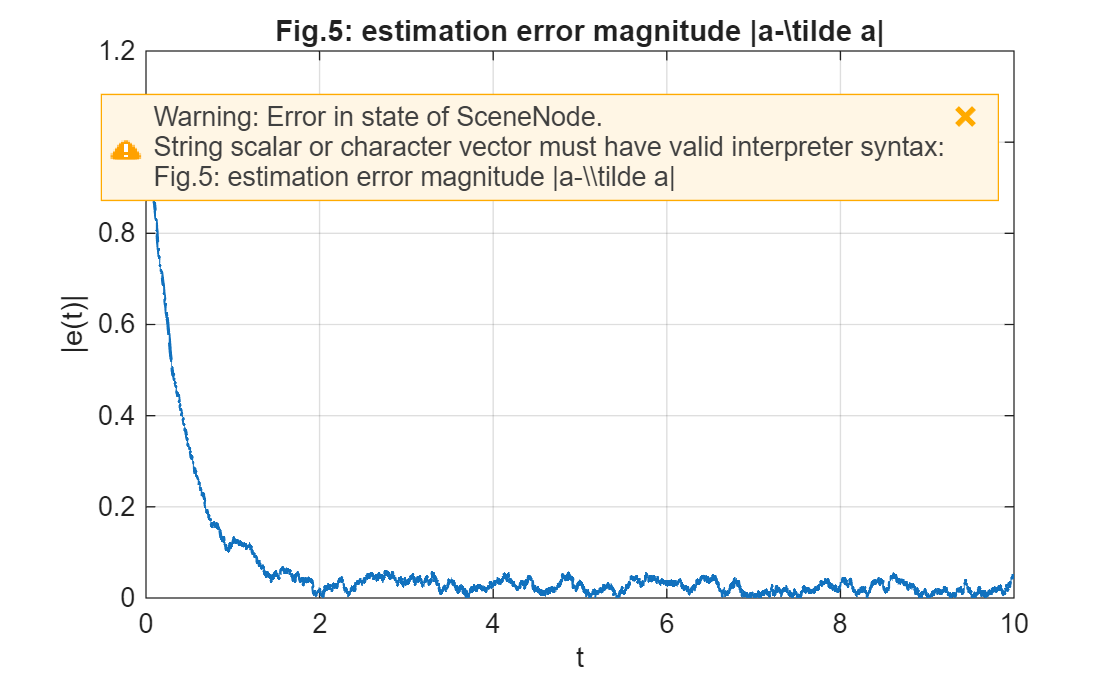


% 2) state error
figure;
plot(tk, abs(sim.e), 'LineWidth', 1.2);
grid on; xlabel('t'); ylabel('|e(t)|');
title('Fig.5: estimation error magnitude |a-\tilde a|');

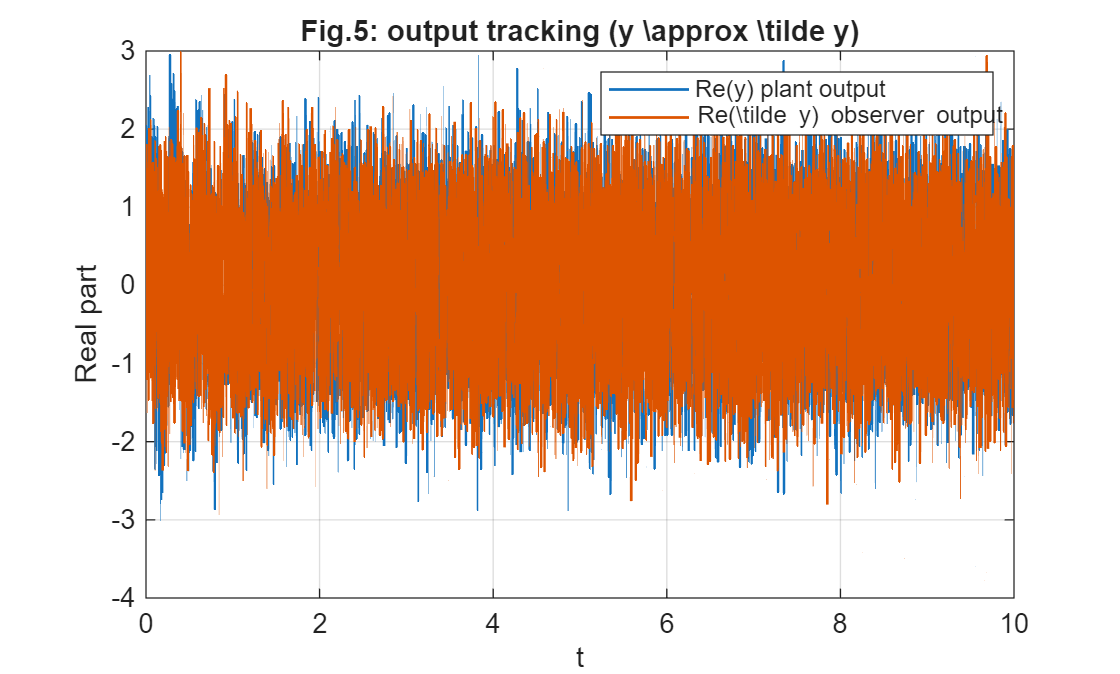


% 3) output tracking: y vs ytil
figure;
plot(tk, real(sim.y), 'LineWidth', 1.0); hold on;
plot(tk, real(sim.ytil), 'LineWidth', 1.0);
grid on; xlabel('t'); ylabel('Real part');
legend('Re(y) plant output','Re(\tilde y) observer output');
title('Fig.5: output tracking (y \approx \tilde y)');

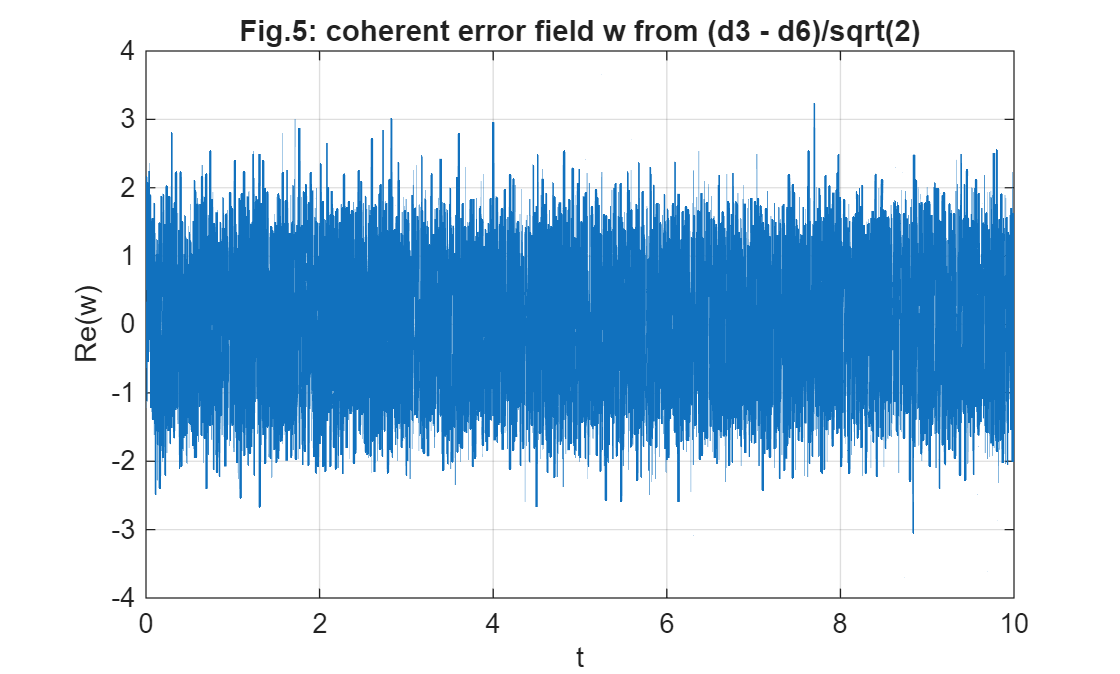


% 4) coherent error field w
figure;
plot(tk, real(sim.w), 'LineWidth', 1.0);
grid on; xlabel('t'); ylabel('Re(w)');
title('Fig.5: coherent error field w from (d3 - d6)/sqrt(2)');


% Steady-state <e*e> estimate
idx = round(0.8*N):(N-1);
e_ss = mean(abs(sim.e(idx)).^2);
fprintf('Estimated steady-state <e*e> ~ %.4g\n', e_ss);

Estimated steady-state <e*e> ~ 0.000573
